## Circular aperture test

This theory test demo reproduces Fig 4 in paper of:  Fabin Shen, "Fast-Fourier-transform based numerical integration method for the Rayleigh-Sommerfeld diffraction formula." Applied Optics 45(6):1102-1110,  2006.

close all;clear;clc;
format compact;

rng('default'); % fixed seed for reproducibility
addpath(genpath('../function/'));  % Add funtion path with sub-folders


### Odd number

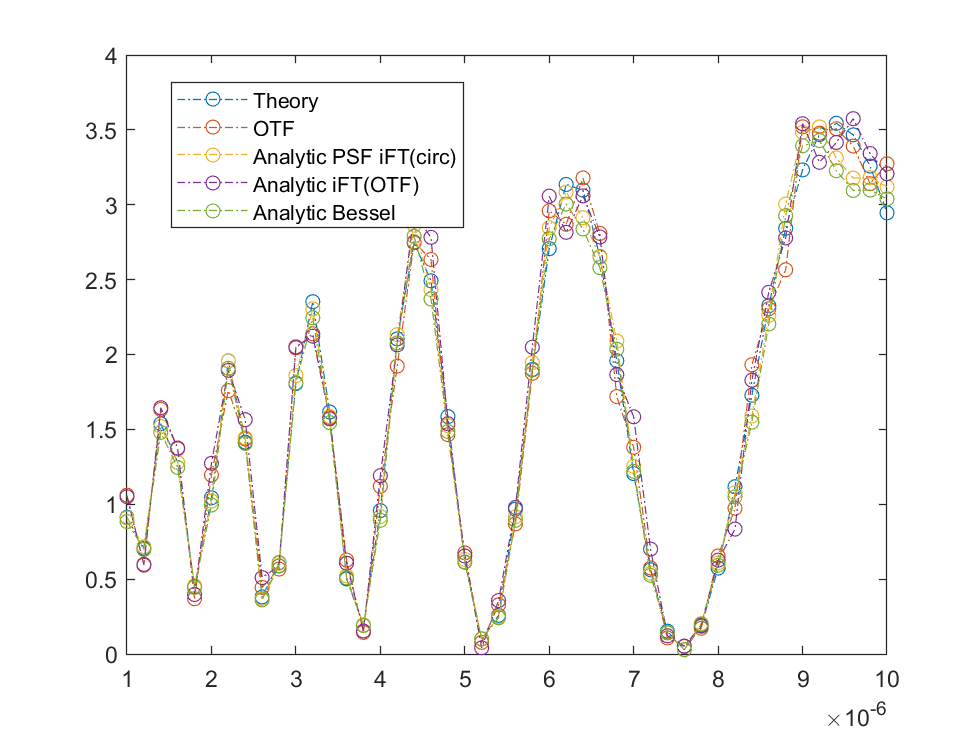

N = 513;
lambda = 0.5e-6;        k = 2*pi/lambda;
a = 10*lambda;
sampling_rate = 0.1*lambda;

mask_DI = zeros([N N]);
v = (1:N) - round((N+1)/2);
u = (1:N) - round((N+1)/2);
[x,y] = meshgrid(v,u);
mask_DI(sqrt(x.^2 + y.^2) <= a/sampling_rate) = 1;
U1 = mask_DI;

z_vec = 1e-6:2e-7:10e-6;
Iz = z_vec.*(exp(1i*k*z_vec)./z_vec - exp(1i*k*sqrt(z_vec.^2+a^2))./sqrt(z_vec.^2+a^2));

I_otf = zeros(numel(z_vec), 1);
I_psf = zeros(numel(z_vec), 1);
I_psf_ift1 = zeros(numel(z_vec), 1);
I_psf_ift2 = zeros(numel(z_vec), 1);

cc = 0;

for z = z_vec
    
    cc = cc + 1;
%     disp([num2str(cc) '/' num2str(numel(z_vec))])
    
    [otf, psf2d_ift, psf2d_analytical, psf2d_bessel] = prop_kernel(N, N, lambda, sampling_rate, z, 10000);  
    
    U_FFTDI = FieldForwardProp(U1, otf);
    I_otf(cc) = U_FFTDI(round(size(U_FFTDI,1)/2), round(size(U_FFTDI, 2)/2));

    U_FFTDI = FieldForwardPropPSF(U1, psf2d_analytical);
    I_psf(cc) = U_FFTDI(round(size(U_FFTDI,1)/2)+0, round(size(U_FFTDI, 2)/2)+0);
    
    U_FFTDI = FieldForwardPropPSF(U1, psf2d_ift);
    I_psf_ift1(cc) = U_FFTDI(round(size(U_FFTDI,1)/2)+0, round(size(U_FFTDI, 2)/2)+0);
    
    U_FFTDI = FieldForwardPropPSF(U1, psf2d_bessel);   % need a scale factor
    I_psf_ift2(cc) = U_FFTDI(round(size(U_FFTDI,1)/2)+0, round(size(U_FFTDI, 2)/2)+0);
end

% figure;
% plot(z_vec, [abs(Iz').^2 abs(I_otf).^2 abs(I_psf).^2 abs(I_psf_ift).^2], '-.o');
% legend('Theory', 'OTF', 'PSF', 'Analytic PSF');

figure;
plot(z_vec, [abs(Iz').^2 abs(I_otf).^2 abs(I_psf).^2 abs(I_psf_ift1).^2 abs(I_psf_ift2).^2/100], '-.o');
legend('Theory', 'OTF', 'Analytic PSF iFT(circ)', 'Analytic iFT(OTF)',  'Analytic Bessel', 'Location', 'Best');

### Even number

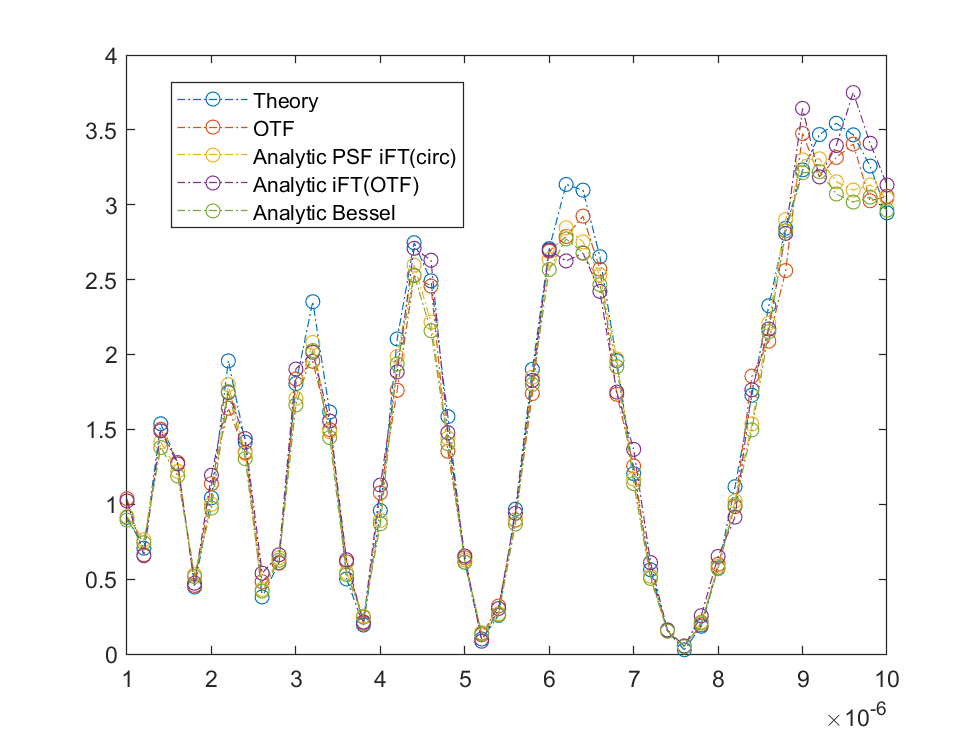

N = 512;
lambda = 0.5e-6;        k = 2*pi/lambda;
a = 10*lambda;
sampling_rate = 0.1*lambda;

mask_DI = zeros([N N]);
v = (1:N) - round((N+1)/2);
u = (1:N) - round((N+1)/2);
[x,y] = meshgrid(v,u);
mask_DI(sqrt(x.^2 + y.^2) <= a/sampling_rate) = 1;
U1 = mask_DI;

z_vec = 1e-6:2e-7:10e-6;
Iz = z_vec.*(exp(1i*k*z_vec)./z_vec - exp(1i*k*sqrt(z_vec.^2+a^2))./sqrt(z_vec.^2+a^2));

I_otf = zeros(numel(z_vec), 1);
I_psf = zeros(numel(z_vec), 1);
I_psf_ift1 = zeros(numel(z_vec), 1);
I_psf_ift2 = zeros(numel(z_vec), 1);

cc = 0;

for z = z_vec
    
    cc = cc + 1;
%     disp([num2str(cc) '/' num2str(numel(z_vec))])
    
    [otf, psf2d_ift, psf2d_analytical, psf2d_bessel] = prop_kernel(N, N, lambda, sampling_rate, z, 10000);  
    
    U_FFTDI = FieldForwardProp(U1, otf);
    I_otf(cc) = U_FFTDI(round(size(U_FFTDI,1)/2)+0, round(size(U_FFTDI, 2)/2)+0);

    U_FFTDI = FieldForwardPropPSF(U1, psf2d_analytical);
    I_psf(cc) = U_FFTDI(round(size(U_FFTDI,1)/2)+0, round(size(U_FFTDI, 2)/2)+0);
    
    U_FFTDI = FieldForwardPropPSF(U1, psf2d_ift);
    I_psf_ift1(cc) = U_FFTDI(round(size(U_FFTDI,1)/2)+0, round(size(U_FFTDI, 2)/2)+0);
    
    U_FFTDI = FieldForwardPropPSF(U1, psf2d_bessel);   % need a scale factor
    I_psf_ift2(cc) = U_FFTDI(round(size(U_FFTDI,1)/2)+0, round(size(U_FFTDI, 2)/2)+0);
end

% figure;
% plot(z_vec, [abs(Iz').^2 abs(I_otf).^2 abs(I_psf).^2 abs(I_psf_ift).^2], '-.o');
% legend('Theory', 'OTF', 'PSF', 'Analytic PSF');

figure;
plot(z_vec, [abs(Iz').^2 abs(I_otf).^2 abs(I_psf).^2 abs(I_psf_ift1).^2 abs(I_psf_ift2).^2/100], '-.o');
legend('Theory', 'OTF', 'Analytic PSF iFT(circ)', 'Analytic iFT(OTF)',  'Analytic Bessel', 'Location', 'Best');

## Single Slit test

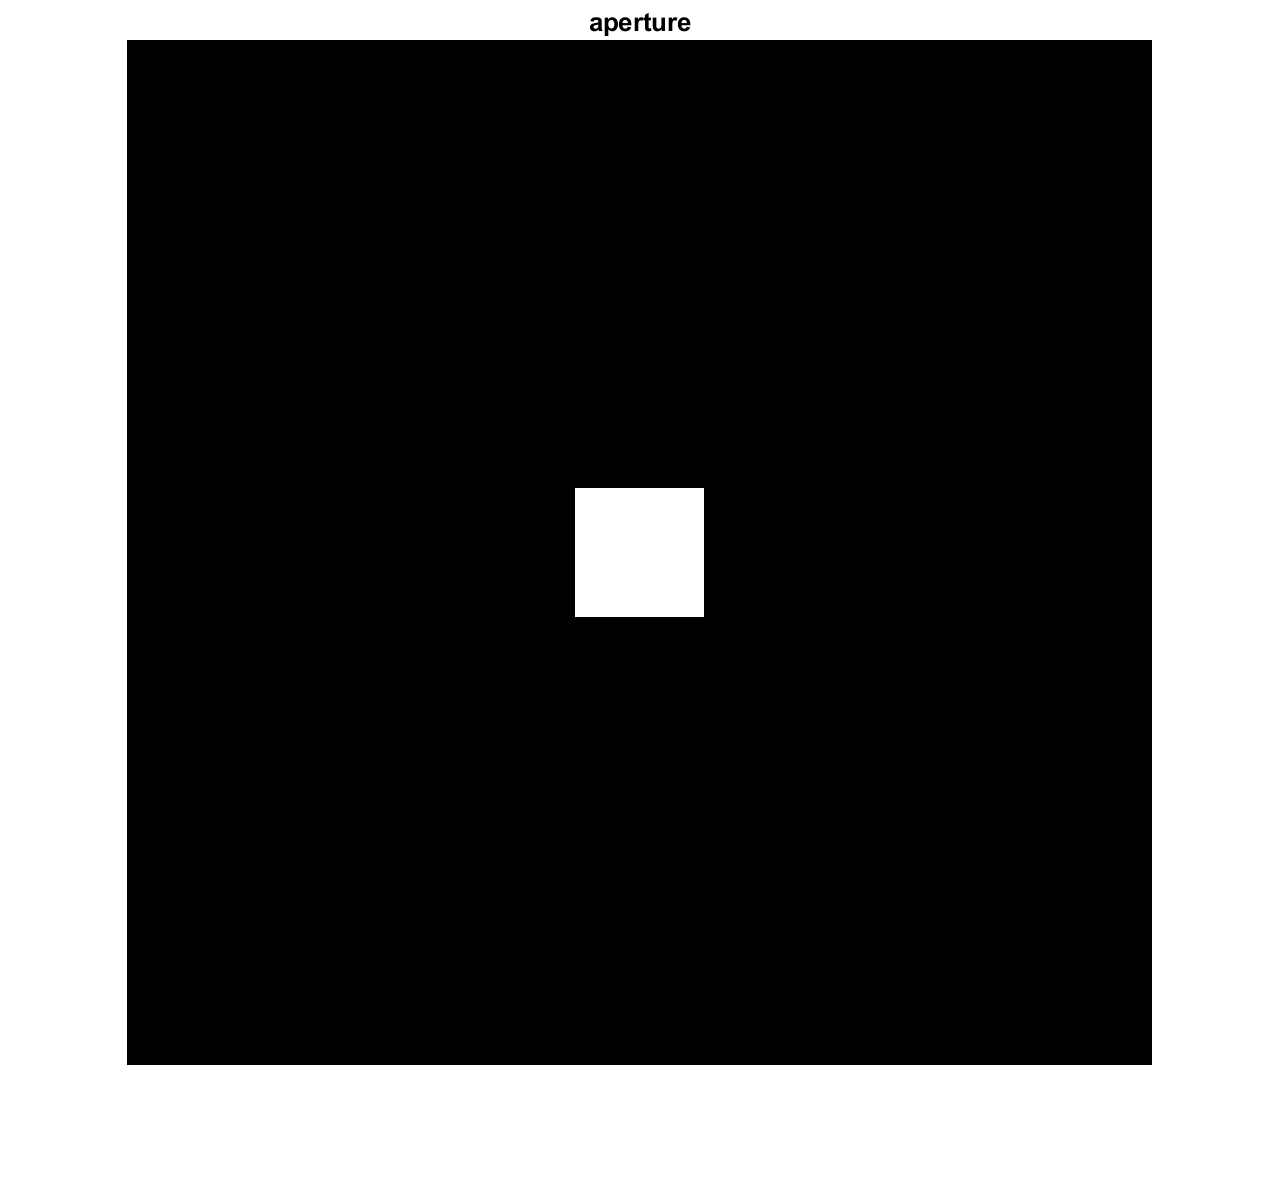

clear
N = 1025;
pdim = [N N];
lambda = 0.5e-6;
width = 10e-6;
sampling_rate = 80e-6/N;
z = 100e-6;
xx = (1:N) - round((N+1)/2);

mask_DI = ones([N N]);
v = (1:N) - round((N+1)/2);
u = (1:N) - round((N+1)/2);
[x, y] = meshgrid(v,u);
mask_DI( (abs(x) > width/sampling_rate/2) | (abs(y) > width/sampling_rate/2)) = 0;
% mask_DI(sqrt(x.^2 + y.^2) > width/sampling_rate) = 0;
U1 = mask_DI;


[otf, psf] = prop_kernel(N, N, lambda, sampling_rate, z, 10000);  

U_FFTDI = FieldForwardProp(U1, otf);
I_otf = abs(U_FFTDI).^2;

U_FFTDI = FieldForwardPropPSF(U1, psf);
I_psf = abs(U_FFTDI).^2;
    
    
% DI single slit
% U0_DI = sdoss_gen_scalarU(pdim, 1, 'unitary', 'DI');
% mask_DI = sdoss_gen_mask(pdim, 1, 'square', [], width/sampling_rate, 'DI');
% U1_DI = sdoss_aperture(U0_DI, mask_DI);
% U2_DI = sdoss_propagation(U1_DI, lambda, sampling_rate, z, 'DI');
% img_DI = sdoss_sensor(U2_DI, pdim, 'DI');
% 
% % AS single slit
% U0_AS = sdoss_gen_scalarU(pdim, 1, 'unitary', 'AS');
% mask_AS = sdoss_gen_mask(pdim, 1, 'square', [], width/sampling_rate, 'AS');
% U1_AS = sdoss_aperture(U0_AS, mask_AS);
% U2_AS = sdoss_propagation(U1_AS, lambda, sampling_rate, z, 'AS');
% img_AS = sdoss_sensor(U2_AS, pdim, 'AS');

figure;     imshow(U1, []);     title('aperture');

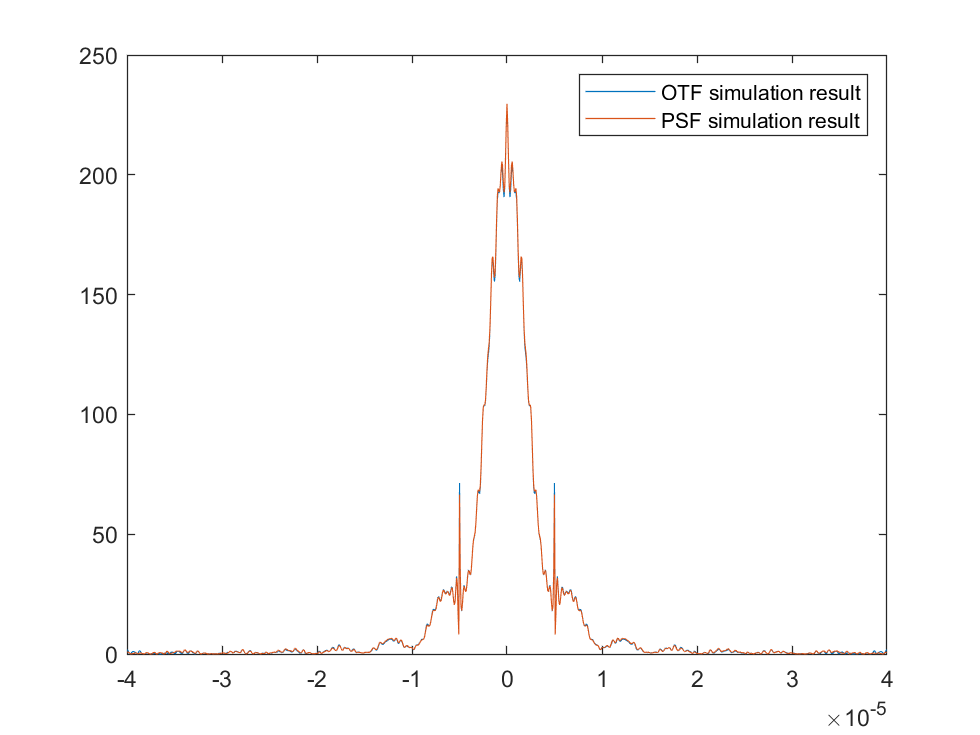

% show results
figure;     plot((xx*sampling_rate)', [sum(I_otf)' sum(I_psf)']);
legend('OTF simulation result', 'PSF simulation result');

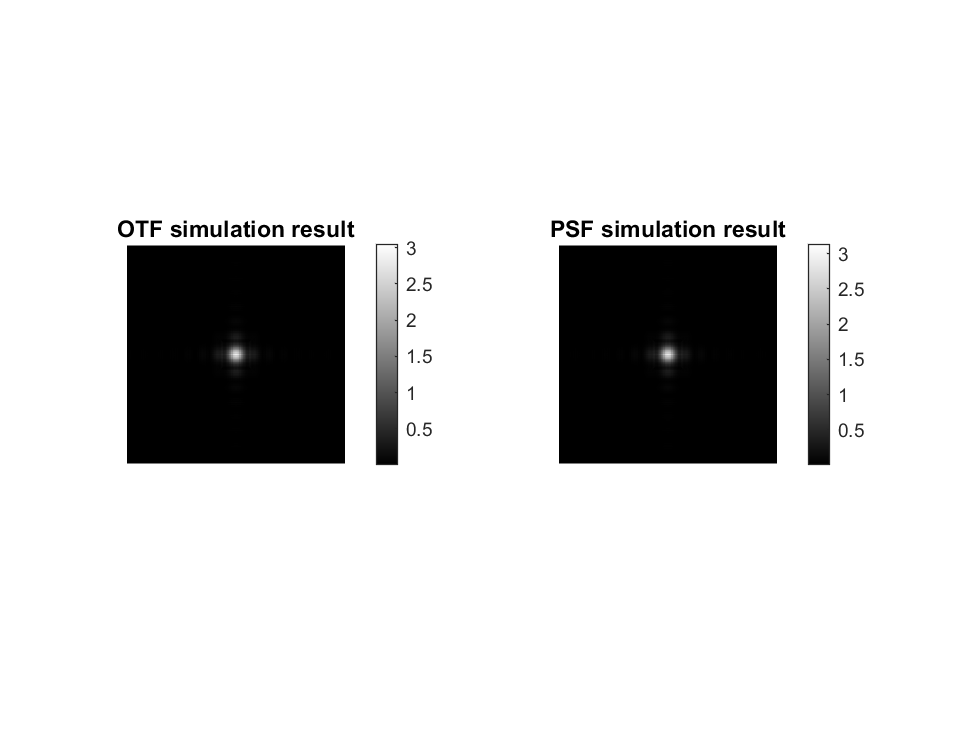


figure; 
subplot(121); imshow(I_otf, []); colorbar; title('OTF simulation result');
subplot(122); imshow(I_psf, []); colorbar; title('PSF simulation result');

## Propgation test

### Even number

close all; clear; clc;

rng('default'); % fixed seed for reproducibility
addpath(genpath('./function/'));  % Add funtion path with sub-folders
format long;


% Parameters of the hologram system
sys.lambda = 632.8e-9;   % illumination wavelength
sys.NA     = 0.4;        % sys.NA of the objective lens
sys.M      = 1;          % Magnification of the objective lens
sys.pps    = 3.45e-6*1;  % pixel pitch of CCD camera
sys.z0     = 10e-3;      % distance between the hologram and the center plane of the 3D object

sys.Ns     = 512;        % pixel number of the camera sensor
sys.Ns_bound = 0;        % boundary crop of the sensor
% sys.Ns_bound = round((sys.Ns-1)/8)

% parameters of the object
obj.Nz      = 3;         % axial size
obj.ppo     = 3450e-9/4;    % pixel pitch of the object, sys.pps/20
obj.dz      = 1000e-6;     % depth interval of the object slices

obj.z_range = sys.z0 + ((1:obj.Nz) - round((obj.Nz+1)/2))*obj.dz;      % distance between the hologram and the center plane of the 3D object

M = sys.M*sys.pps/obj.ppo;
% obj.Nxy    = round(sys.Ns*sys.pps/obj.ppo) + sys.Ns_bound*2   %lateral size (must be an odd number!)
obj.Nxy     = round((sys.Ns+ sys.Ns_bound*2)*M)    %lateral size (must be an odd number!)

obj = struct with fields:
         Nz: 3
        ppo: 8.625000000000000e-07
         dz: 1.000000000000000e-03
    z_range: [0.009000000000000 0.010000000000000 0.011000000000000]
        Nxy: 2048

Nxy_bound   = round(obj.Nxy/16)

Nxy_bound =    128

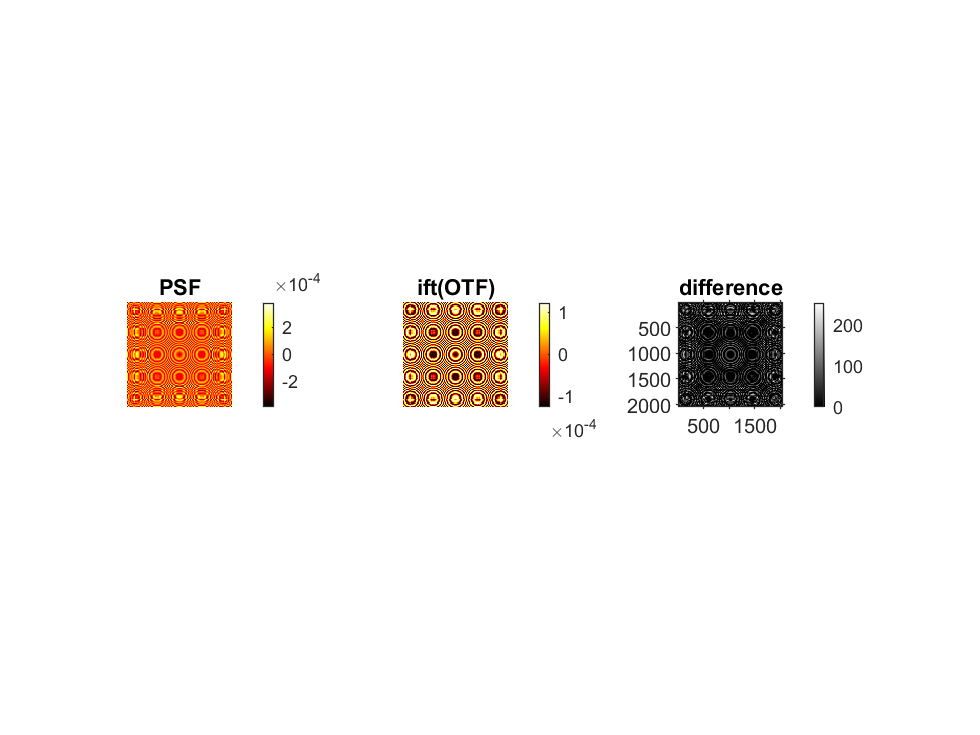

% Nxy_bound = 0

N_random = round(obj.Nxy*0.02);

% point_size = 10e-6/(sys.pps/20);      % pixel size of one random point, 10e-6/(3.45e-6*8/20)
point_size = 25;      % pixel size of one random point, 10e-6/(3.45e-6*8/20)
obj3d = randomScatter(obj.Nxy, obj.Nz, N_random, point_size, 0);   % Randomly distributed scatter object
% obj3d = zeros(size(obj3d));
% obj3d(round(size(obj3d,1)/2), round(size(obj3d,2)/2)) = 1;

% generate propagation kernel of the imaging system
[otf, psf, psf_ift] = prop_kernel(obj.Nxy, obj.Nxy, sys.lambda, obj.ppo, obj.z_range, sys.NA);    


% confirm PSF and analytical PSF
figure;
show_psfotf((psf), 131, 'PSF', obj.Nz);
show_psfotf(psf_ift, 132, 'ift(OTF)', obj.Nz);
subplot(1,3,3); difference = imshowpair(real((psf)), real((psf_ift)), 'diff');  title('difference'); axis on; colorbar;

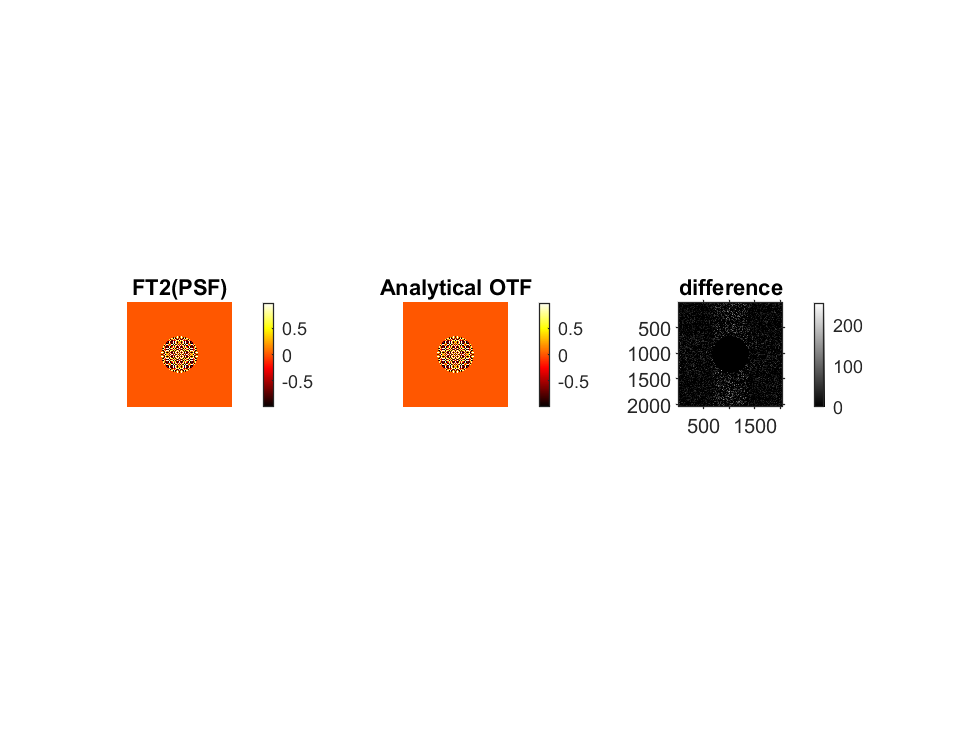



% confirm PSF calculated from OTF
figure;
show_psfotf(FT2(psf), 131, 'FT2(PSF)', obj.Nz);
show_psfotf(otf, 132, 'Analytical OTF', obj.Nz);
subplot(1,3,3); difference = imshowpair(real(FT2(psf)), real(otf), 'diff');  title('difference'); axis on; colorbar;

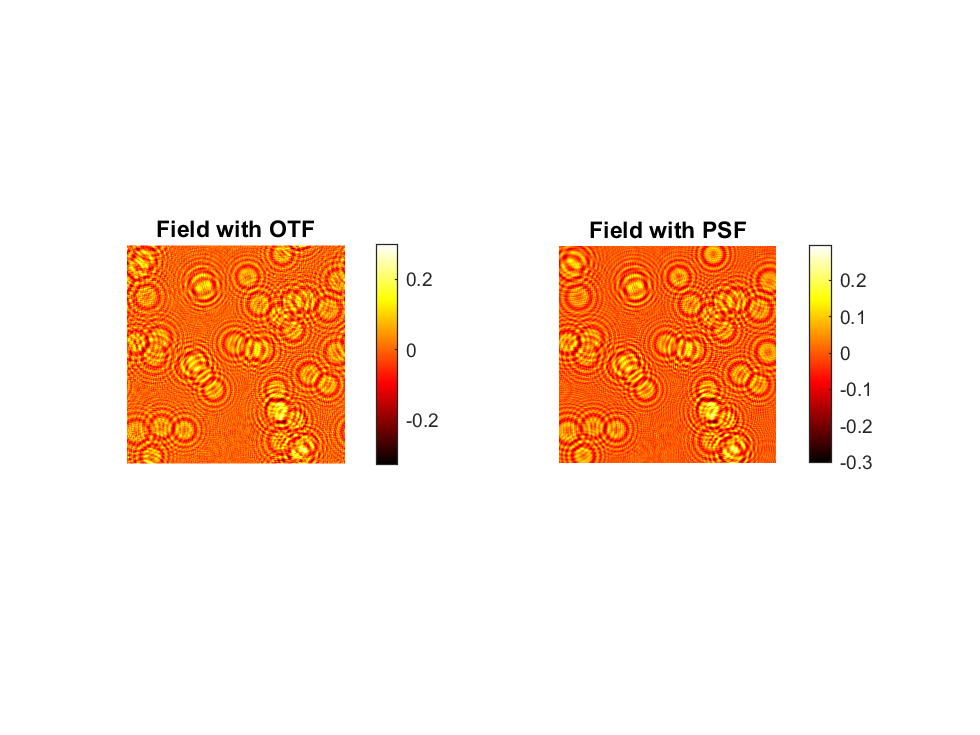



field_otf = FieldForwardProp(obj3d, otf);
re_field_otf = FieldBackwardProp(field_otf, otf);

field_psf = FieldForwardPropPSF(obj3d, psf);
re_field_psf = FieldBackwardPropPSF(field_psf, psf);

% % Test single plane
% figure;
% subplot(221); imshow(real(field_otf), []); title('Field with OTF'); colormap(hot(256)); colorbar;
% subplot(222); imshow(real(re_field_otf), []); title('reconstructed field with OTF'); colormap(hot(256)); colorbar;
% 
% subplot(223); imshow(real(field_psf), []); title('Field with PSF'); colormap(hot(256)); colorbar;
% subplot(224); imshow(real(re_field_psf), []); title('reconstructed field with PSF'); colormap(hot(256)); colorbar;

% Test multiple plane
figure;
subplot(121); imshow(real(field_otf), []); title('Field with OTF'); colormap(hot(256)); colorbar;
subplot(122); imshow(real(field_psf), []); title('Field with PSF'); colormap(hot(256)); colorbar;

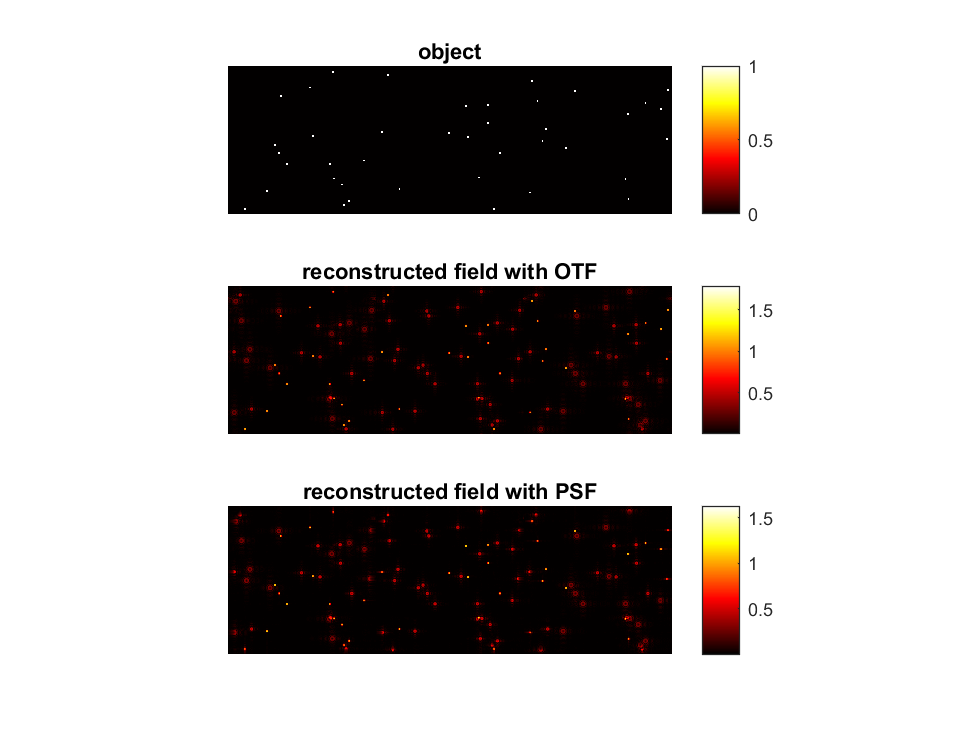


figure;
show_data((obj3d), 311, 'object');
show_data(real(re_field_otf), 312, 'reconstructed field with OTF');
show_data(real(re_field_psf), 313, 'reconstructed field with PSF');

### Odd number

close all; clear; clc;

rng('default'); % fixed seed for reproducibility
addpath(genpath('./function/'));  % Add funtion path with sub-folders
format long;

% Parameters of the hologram system
sys.lambda = 632.8e-9;   % illumination wavelength
sys.NA     = 0.4;        % sys.NA of the objective lens
sys.M      = 1;          % Magnification of the objective lens
sys.pps    = 3.45e-6*1;  % pixel pitch of CCD camera
sys.z0     = 10e-3;      % distance between the hologram and the center plane of the 3D object

sys.Ns     = 513;        % pixel number of the camera sensor
sys.Ns_bound = 0;        % boundary crop of the sensor
% sys.Ns_bound = round((sys.Ns-1)/8)

% parameters of the object
obj.Nz      = 3;         % axial size
obj.ppo     = 3450e-9/4;    % pixel pitch of the object, sys.pps/20
obj.dz      = 1000e-6;     % depth interval of the object slices

obj.z_range = sys.z0 + ((1:obj.Nz) - round((obj.Nz+1)/2))*obj.dz;      % distance between the hologram and the center plane of the 3D object

M = sys.M*sys.pps/obj.ppo;
% obj.Nxy    = round(sys.Ns*sys.pps/obj.ppo) + sys.Ns_bound*2   %lateral size (must be an odd number!)
obj.Nxy     = round((sys.Ns+ sys.Ns_bound*2)*M)    %lateral size (must be an odd number!)

obj = struct with fields:
         Nz: 3
        ppo: 8.625000000000000e-07
         dz: 1.000000000000000e-03
    z_range: [0.009000000000000 0.010000000000000 0.011000000000000]
        Nxy: 2052

Nxy_bound   = round(obj.Nxy/16)

Nxy_bound =    128

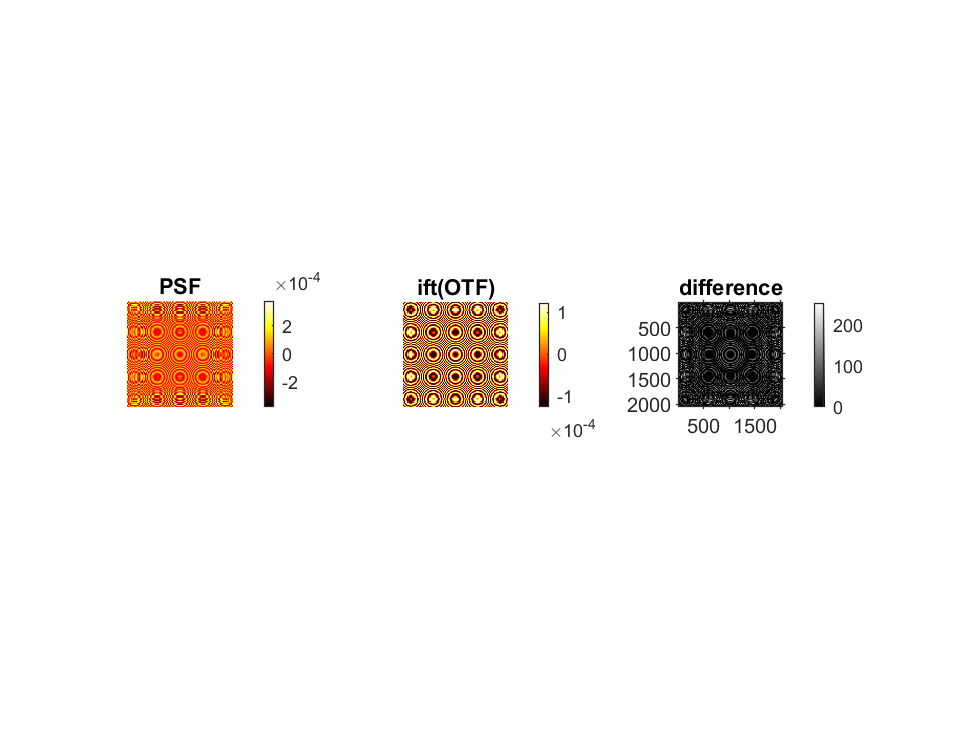

% Nxy_bound = 0

N_random = round(obj.Nxy*0.02);

% point_size = 10e-6/(sys.pps/20);      % pixel size of one random point, 10e-6/(3.45e-6*8/20)
point_size = 25;      % pixel size of one random point, 10e-6/(3.45e-6*8/20)
obj3d = randomScatter(obj.Nxy, obj.Nz, N_random, point_size, 0);   % Randomly distributed scatter object
% obj3d = zeros(size(obj3d));
% obj3d(round(size(obj3d,1)/2), round(size(obj3d,2)/2)) = 1;

% generate propagation kernel of the imaging system
[otf, psf, psf_ift] = prop_kernel(obj.Nxy, obj.Nxy, sys.lambda, obj.ppo, obj.z_range, sys.NA);    


% confirm PSF and analytical PSF
figure;
show_psfotf((psf), 131, 'PSF', obj.Nz);
show_psfotf(psf_ift, 132, 'ift(OTF)', obj.Nz);
subplot(1,3,3); difference = imshowpair(real((psf)), real((psf_ift)), 'diff');  title('difference'); axis on; colorbar;

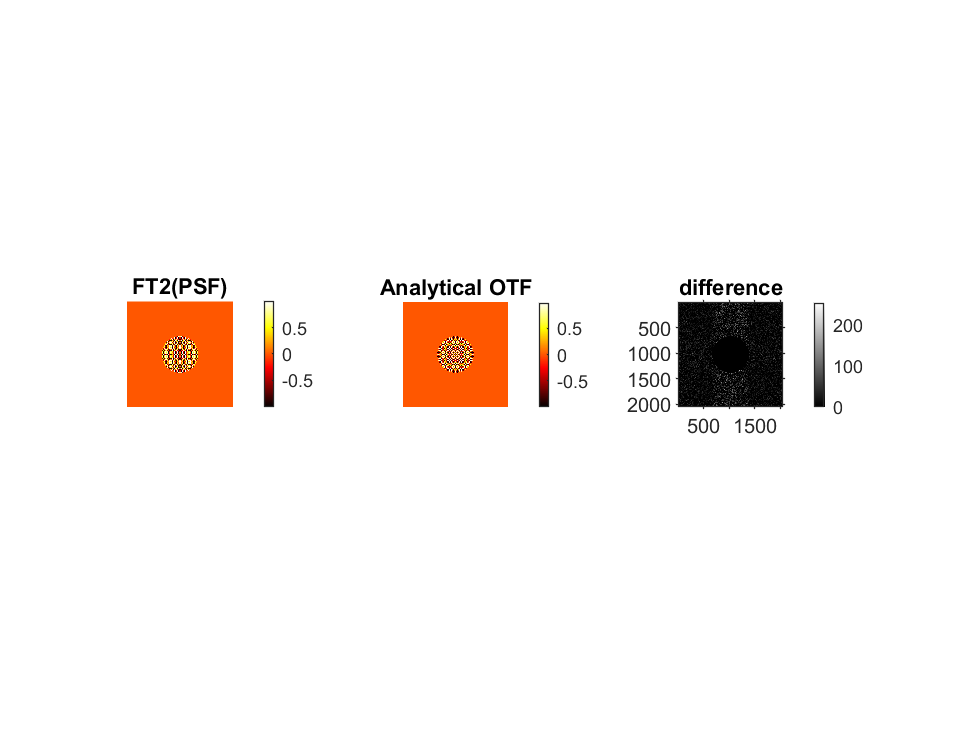



% confirm PSF calculated from OTF
figure;
show_psfotf(FT2(psf), 131, 'FT2(PSF)', obj.Nz);
show_psfotf(otf, 132, 'Analytical OTF', obj.Nz);
subplot(1,3,3); difference = imshowpair(real(FT2(psf)), real(otf), 'diff');  title('difference'); axis on; colorbar;

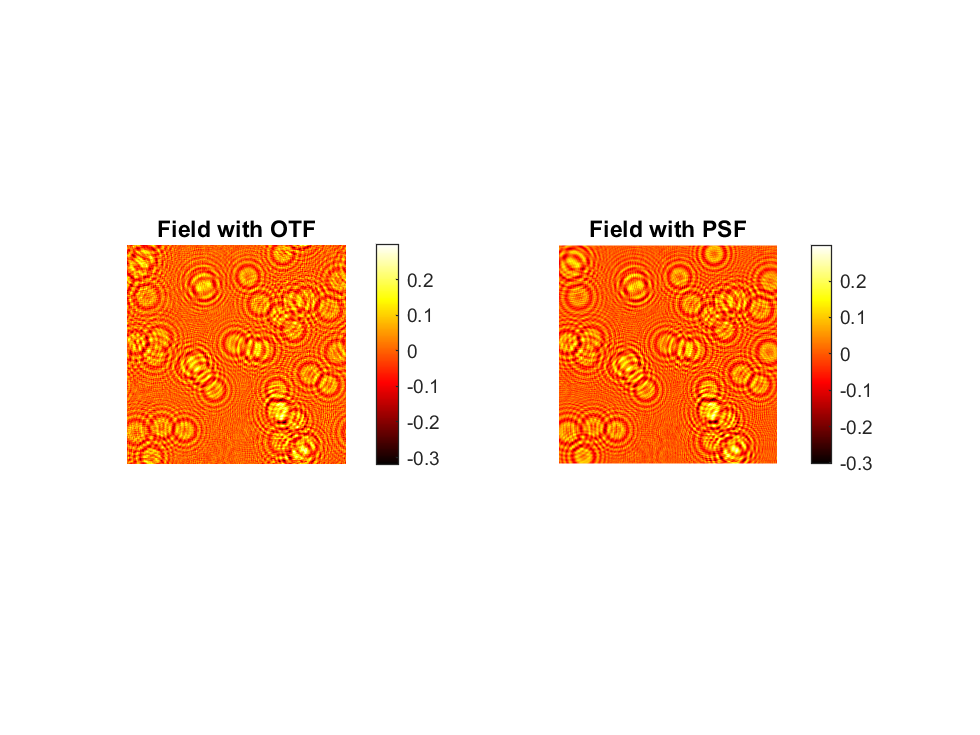



field_otf = FieldForwardProp(obj3d, otf);
re_field_otf = FieldBackwardProp(field_otf, otf);

field_psf = FieldForwardPropPSF(obj3d, psf);
re_field_psf = FieldBackwardPropPSF(field_psf, psf);

% % Test single plane
% figure;
% subplot(221); imshow(real(field_otf), []); title('Field with OTF'); colormap(hot(256)); colorbar;
% subplot(222); imshow(real(re_field_otf), []); title('reconstructed field with OTF'); colormap(hot(256)); colorbar;
% 
% subplot(223); imshow(real(field_psf), []); title('Field with PSF'); colormap(hot(256)); colorbar;
% subplot(224); imshow(real(re_field_psf), []); title('reconstructed field with PSF'); colormap(hot(256)); colorbar;

% Test multiple plane
figure;
subplot(121); imshow(real(field_otf), []); title('Field with OTF'); colormap(hot(256)); colorbar;
subplot(122); imshow(real(field_psf), []); title('Field with PSF'); colormap(hot(256)); colorbar;

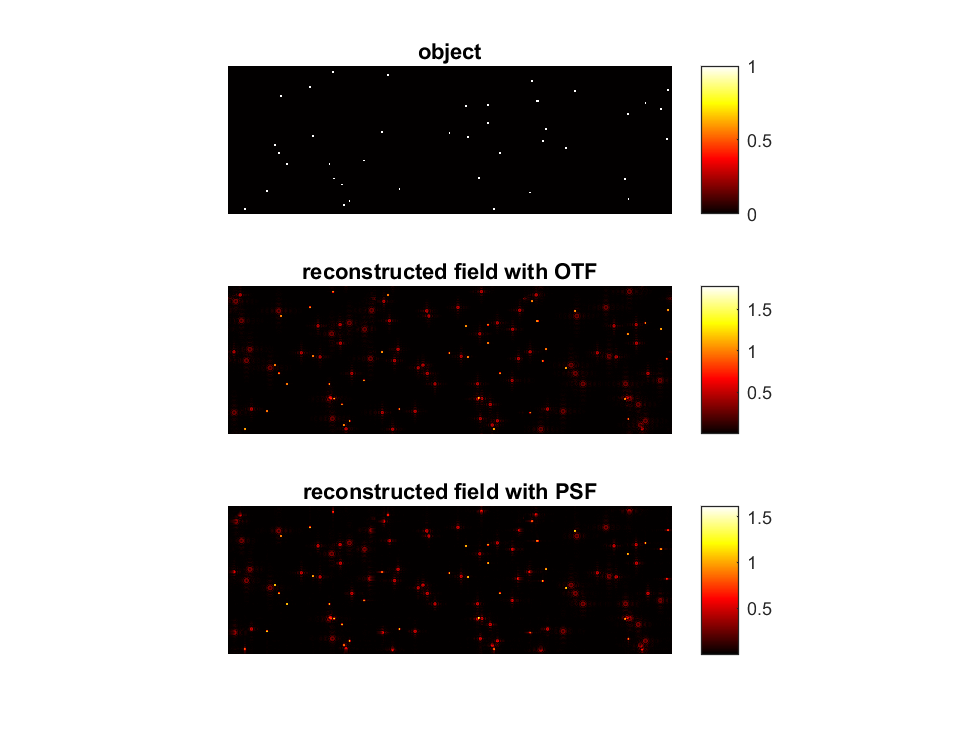


figure;
show_data((obj3d), 311, 'object');
show_data(real(re_field_otf), 312, 'reconstructed field with OTF');
show_data(real(re_field_psf), 313, 'reconstructed field with PSF');